Графики решений явными методами

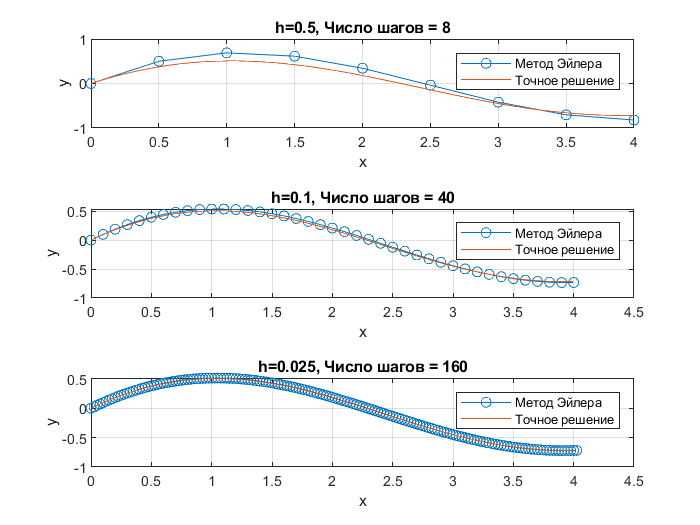

F = @(x,y) cos(x) - y;
Realf = @(x) 1/2*(-exp(-x) + sin(x) + cos(x));
x = linspace(0, 4);
f = Realf(x);
x_0 = 0;
y_0 = 0;
RightBorder = 4;
h = 1/2;

%% Метод Эйлера
[X,Y] = ExplicitRungeKuttaMethod (F, 1, x_0, y_0, h, RightBorder);
[X2,Y2] = ExplicitRungeKuttaMethod (F, 1, x_0, y_0, h/5, RightBorder);
[X3,Y3] = ExplicitRungeKuttaMethod (F, 1, x_0, y_0, h/20, RightBorder);

figure
tiledlayout(3,1);

nexttile;
plot (X, Y(1,:),'-o', x, f)
title('h=0.5, Число шагов = 8')
legend ('Метод Эйлера', 'Точное решение')
grid on
xlabel('x')
ylabel('y')

nexttile
plot (X2, Y2(1,:),'-o', x, f)
title('h=0.1, Число шагов = 40')
legend ('Метод Эйлера', 'Точное решение')
grid on
xlabel('x')
ylabel('y')
hold on
grid on

nexttile
plot (X3, Y3(1,:),'-o', x, f)
title('h=0.025, Число шагов = 160')
legend ('Метод Эйлера', 'Точное решение')
grid on
xlabel('x')
ylabel('y')
hold on
grid on

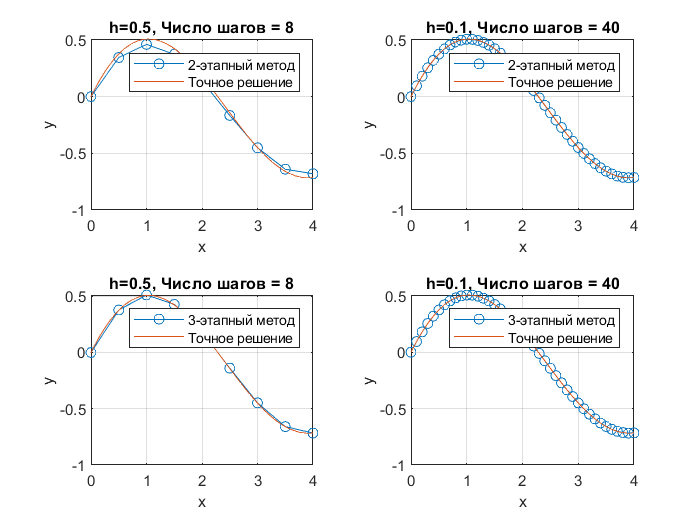


%% Методы Хойна и Симпсона
[X,Y] = ExplicitRungeKuttaMethod (F, 2, x_0, y_0, h, RightBorder);
[X2,Y2] = ExplicitRungeKuttaMethod (F, 2, x_0, y_0, h/5, RightBorder);

[Xs,Ys] = ExplicitRungeKuttaMethod (F, 3, x_0, y_0, h, RightBorder);
[X2s,Y2s] = ExplicitRungeKuttaMethod (F, 3, x_0, y_0, h/5, RightBorder);

figure
tiledlayout(2,2);

nexttile;
plot (X, Y(1,:),'-o', x, f)
title('h=0.5, Число шагов = 8')
legend ('2-этапный метод', 'Точное решение')
grid on
xlabel('x')
ylabel('y')

nexttile
plot (X2, Y2(1,:),'-o', x, f)
title('h=0.1, Число шагов = 40')
legend ('2-этапный метод', 'Точное решение')
grid on
xlabel('x')
ylabel('y')
hold on
grid on

nexttile;
plot (Xs, Ys(1,:),'-o', x, f)
title('h=0.5, Число шагов = 8')
legend ('3-этапный метод', 'Точное решение')
grid on
xlabel('x')
ylabel('y')

nexttile
plot (X2s, Y2s(1,:),'-o', x, f)
title('h=0.1, Число шагов = 40')
legend ('3-этапный метод', 'Точное решение')
grid on
xlabel('x')
ylabel('y')
hold on
grid on

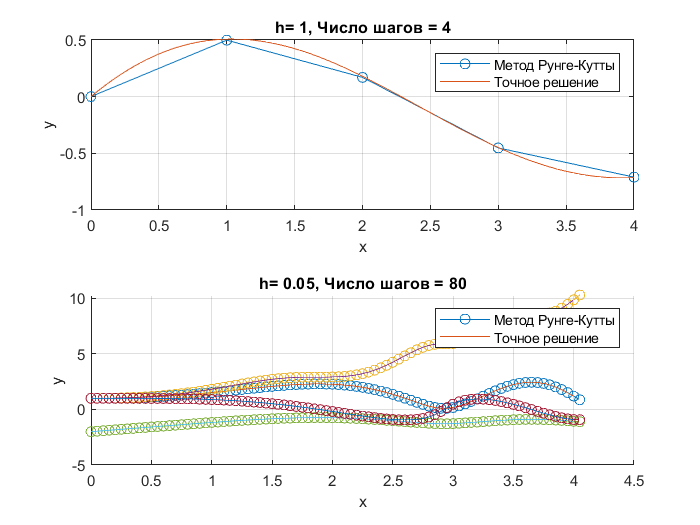


%% Классический метод Рунге-Кутты

F = @(x,y) cos(x) - y;
Realf = @(x) 1/2*(-exp(-x) + sin(x) + cos(x));
x = linspace(0, 4);
f = Realf(x);
x_0 = 0;
y_0 = 0;
RightBorder = 4;
h = 1;

[X,Y] = ExplicitRungeKuttaMethod (F, 4, x_0, y_0, h, RightBorder);

figure
tiledlayout(2,1);

nexttile;
plot (X, Y(1,:),'-o', x, f)
title('h= 1, Число шагов = 4')
legend ('Метод Рунге-Кутты', 'Точное решение')
grid on
xlabel('x')
ylabel('y')


F = @(x,y) [ x*y(2)^(1/4)*y(4);
             x*exp(y(3)+2)*y(4)^(2);
             sin(y(4));
             -1*x*log(y(1));
             ];
x_0 = 0;
y_0 = [1; 1; -2; 1];
RightBorder=4;
h = 0.05;

[x,f] = DormanPrince(F,x_0,y_0, h, RightBorder, 10^-10);
[X,Y] = ExplicitRungeKuttaMethod (F, 4, x_0, y_0, h, RightBorder);

nexttile;
hold on
plot (X, Y(1,:),'-o', x, f(1,:))
plot (X, Y(2,:),'-o', x, f(2,:))
plot (X, Y(3,:),'-o', x, f(3,:))
plot (X, Y(4,:),'-o', x, f(4,:))
title('h= 0.05, Число шагов = 80')
legend ('Метод Рунге-Кутты', 'Точное решение')

grid on
xlabel('x')
ylabel('y')


%% График сравнения всех явных методов
[X,Y] = ExplicitRungeKuttaMethod (F, 1, x_0, y_0, h/2, RightBorder);
[X2,Y2] = ExplicitRungeKuttaMethod (F, 2, x_0, y_0, h, RightBorder);
[X3,Y3] = ExplicitRungeKuttaMethod (F, 3, x_0, y_0, h, RightBorder);
[X4,Y4] = ExplicitRungeKuttaMethod (F, 4, x_0, y_0, h*2, RightBorder);

figure

tiledlayout(2,2);


nexttile;
plot (X, Y(1,:),'-o', x, f)

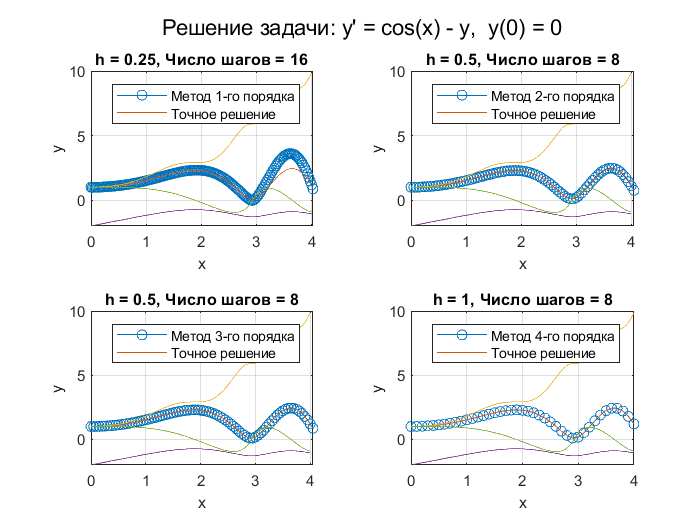

title('h = 0.25, Число шагов = 16')
legend ('Метод 1-го порядка', 'Точное решение')
grid on
xlabel('x')
ylabel('y')

nexttile
plot (X2, Y2(1,:),'-o', x, f)
title('h = 0.5, Число шагов = 8')
legend ('Метод 2-го порядка', 'Точное решение')
grid on
xlabel('x')
ylabel('y')
hold on
grid on

nexttile
plot (X3, Y3(1,:),'-o', x, f)
title('h = 0.5, Число шагов = 8')
legend ('Метод 3-го порядка', 'Точное решение')
grid on
xlabel('x')
ylabel('y')
hold on
grid on

nexttile
plot (X4, Y4(1,:),'-o', x, f)
title('h = 1, Число шагов = 8')
legend ('Метод 4-го порядка', 'Точное решение')
grid on
xlabel('x')
ylabel('y')
hold on
grid on

sgp = sgtitle (" Решение задачи: y' = cos(x) - y,  y(0) = 0 ", 'Color', 'black');

sqp.FontSize = 24;

Графики решений методом Дормана-Принса в сравнение с явными

F = @(x,y) [ exp(y(2));
             x*sin(y(1)/10)];
x_0 = 0;
y_0 = [0;0];
RightBorder = 4.5;
h = 0.05;
%%
[X,Y] = ExplicitRungeKuttaMethod (F, 4, x_0, y_0, h, RightBorder);
[x,f] = DormanPrince(F, x_0,y_0, h, RightBorder, 10^-6);

figure
tiledlayout(1,1);

nexttile;
hold on
plot (X, Y(1,:),'-o',x,f,'-*')
plot (X, Y(2,:),'-o',x,f,'-*')
%title("Решение системы: y'_1 = exp(y_2) and y'_2 = x*sin(y_1/10) , y_1(0)= 0, y_2(0)=0")
title("Величина шага для метода Рунге-Кутты h = 0.05")
legend ({'Классический метод Рунге-Кутты', 'Вложенный метод'},...
    'Location','northwest')
grid on
xlabel('x')
ylabel('y')
%%
%[X,Y] = DormanPrince(F, x_0,y_0, h, RightBorder, 10^-4);
[X2,Y2] = DormanPrince(F, x_0,y_0, h, RightBorder, 10^-6);
[X3,Y3] = DormanPrince(F, x_0,y_0, h, RightBorder, 10^-10);
[x,f] = DormanPrince(F, x_0,y_0, h, RightBorder, 10^-12);

figure
tiledlayout(1,2);

% nexttile;
% hold on
% plot (X, Y(1,:),'-o',x,f)
% plot (X, Y(2,:),'-o',x,f)
% title('tol = 10^{-4}, Число шагов = 3')
% legend ({'Метод Дормана-Принца', 'Точное решение'},...
%     'Location','northwest')
% grid on
% xlabel('x')
% ylabel('y')

nexttile;
hold on
plot (X2, Y2(1,:),'-o',x,f)
plot (X2, Y2(2,:),'-o',x,f)
title('tol = 10^{-6}, Число шагов = 27')
legend ({'Метод Дорманда-Принса', 'Точное решение'},...
    'Location','northwest')
grid on
xlabel('x')
ylabel('y')

nexttile;
hold on
plot (X3, Y3(1,:),'-o',x,f)
plot (X3, Y3(2,:),'-o',x,f)
title('tol = 10^{-10}, Число шагов = 194')
legend ({'Метод Дорманда-Принса', 'Точное решение'},...
    'Location','northwest')
grid on
xlabel('x')
ylabel('y')

sgtitle("Решение системы: y'_1 = exp(y_2) and y'_2 = x*sin(y_1/10) , y_1(0)= 0, y_2(0)=0")

Графики решений неявными методами

%%
% Описание хим. реакций
F = @(x,y)[ -0.04*y(1) + 10^4 * y(2) * y(3); 
             0.04*y(1) - 10^4 * y(2) * y(3) - 3*10^7* y(2)*y(2);
             3*10^7* y(2)*y(2)];
x_0 = 0;
y_0 = [1; 0; 0];

RightBorder = 4;
h = 1/5;
tol = 10^(-8);
% xspan = [0, 4];
% [x,f]= ode45(F, xspan, y_0);

[X,Y] = ImplicitHammerHollingsworth(F, x_0,y_0, h, RightBorder);
[Xd,Yd] = DormanPrince(F, x_0,y_0,h/100,RightBorder, tol);

% figure
% hold on
% grid on
% plot (X,Y(1,:),'-o',x,f(:,1));
% plot (X,Y(2,:),'-o',x,f(:,2));
% plot (X,Y(3,:),'-o',x,f(:,3));

figure
hold on
grid on
plot (X,Y(1,:),'-o',Xd,Yd(1,:));
plot (X,Y(2,:),'-o',Xd,Yd(2,:));
plot (X,Y(3,:),'-o',Xd,Yd(3,:));
title ('tol = 10^{-6}, Число шагов = 1986 для метода Дорманда-Принса')
legend ('Неявный метод с 2-стадиями', 'Метод Дорманда-Принса')
xlabel('x')
ylabel('y')
%%
%Простой пример жесткой задачи
F = @(x,y) -50*(y - cos(x));
x_0 = 0;
y_0 = 0;
h = 1/25;
RightBorder = 2;

[X,Y] = ExplicitRungeKuttaMethod(F, 1, x_0, y_0, h, RightBorder);
[Xim, Yim] = ImplicitEuler (F, x_0, y_0, 0.5, RightBorder);
[x,y] = DormanPrince(F, x_0, y_0, h, RightBorder, 10^-6);
figure
hold on
grid on
plot (X,Y,Xim,Yim,'-o');
plot(x,y, 'r');
title ('h = 1/25 для явного метода Эйлера, h = 1/2 для неявного')
legend ('явный метод Эйлера', 'неявный метод Эйлера', 'вложенный метод Дорманда-Принса')

%%
F = @(x,y) [y(2);               %уравнение Ван-Дер Поля
           20*((1-y(1)^2) * y(2)) - y(1)];
x_0 = 0;
y_0 = [2; 0];
RightBorder = 16;

%[X1,Y1]= DiagonalIRK (F, x_0, y_0, 1/20, RightBorder);
[X1,Y1]= ImplicitEuler (F, x_0, y_0, 1, RightBorder);
[X2,Y2]=ImplicitHammerHollingsworth(F, x_0,y_0, 1, RightBorder);
[x,y] = ODIRK (F, x_0,y_0, 1/100, RightBorder, 10^-6);
%[x,y] = ExplicitRungeKuttaMethod(F, 4, x_0, y_0, 1/20, RightBorder);

figure

hold on
grid on
plot (Y1(1,:),Y1(2,:),'-*');
plot (Y2(1,:),Y2(2,:),'-o');
plot (y(1,:), y(2,:),'green')
xlim([-3, 3]);
ylim([-RightBorder, RightBorder]);
ylabel('y_2')
xlabel ('y_1')
title ('h = 1/20 для явного метода, h = 1/2 для неявных')
%legend ('Диагонально неявный метод 3-го порядка', 'Неявный метод Хаммера-Холлингсуорта 4-го порядка', 'Явный метод 4-го порядка')
legend ('Неявный метод Эйлера', 'Неявный метод Хаммера-Холлингсуорта 4-го порядка', 'Точное решение')

figure
tiledlayout(2,1);
nexttile;
hold on
grid on

plot (X1(1,:),Y1(1,:),'-*');
plot (X2(1,:),Y2(1,:),'-o');
plot (x(1,:), y(1,:), 'green')
xlim([0, RightBorder]);
ylim([-3, 3]);
xlabel('x')
ylabel ('y_1')
title ('h = 1 для неявных методов')
%title ('h = 1/20 для всех методов')
%legend ('Диагонально неявный метод 3-го порядка', 'Неявный метод Хаммера-Холлингсуорта 4-го порядка', 'Явный метод 4-го порядка')
legend ('Неявный метод Эйлера', 'Неявный метод Хаммера-Холлингсуорта 4-го порядка', 'Точное решение')

nexttile;
hold on
grid on

plot (X1(1,:),Y1(2,:),'-*');
plot (X2(1,:),Y2(2,:),'-o');
plot (x(1,:), y(2,:), 'green')
xlim([0, RightBorder]);
ylim([-40, 40]);
xlabel('x')
ylabel ('y_2')
title ('h = 1 для неявных методов')
%title ('h = 1/20 для всех методов')
%legend ('Диагонально неявный метод 3-го порядка', 'Неявный метод Хаммера-Холлингсуорта 4-го порядка', 'Явный метод 4-го порядка')
legend ('Неявный метод Эйлера', 'Неявный метод Хаммера-Холлингсуорта 4-го порядка', 'Точное решение')


Графики решений диагонально неявным методом

% Описание хим. реакций
% F = @(x,y)[ -0.04*y(1) + 10^4 * y(2) * y(3); 
%              0.04*y(1) - 10^4 * y(2) * y(3) - 3*10^7* y(2)*y(2);
%              3*10^7* y(2)*y(2)];
% x_0 = 0;
% y_0 = [1; 0; 0];

F = @(x,y) [y(2);               %уравнение Ван-Дер Поля
           20*((1-y(1)*y(1)) * y(2)) - y(1)];
x_0 = 0;
y_0 = [2; 0];
RightBorder = 16;

h = 1/2;
tol = 10^(-12);

[X1,Y1] = DiagonalIRK(F, x_0,y_0, h, RightBorder);
[X2,Y2] = ImplicitHammerHollingsworth (F, x_0, y_0, h, RightBorder);
[x2,y2] = ExplicitRungeKuttaMethod(F, 4, x_0, y_0, h/10, RightBorder);
[x,y] = DormanPrince(F, x_0,y_0,h/100,RightBorder, tol);

figure

hold on
grid on
plot (Y1(1,:),Y1(2,:),'-*');
plot (Y2(1,:),Y2(2,:),'-o');
plot (y(1,:), y(2,:),'green')
xlim([-3, 3]);
ylim([-RightBorder, RightBorder]);
ylabel('y_2')
xlabel ('y_1')
title ('h = 1/10 для явного метода, h = 1/2 для неявных')
legend ('Диагонально неявный метод 3-го порядка', 'Неявный метод Хаммера-Холлингсуорта 4-го порядка', 'Явный метод 4-го порядка')
%legend ('Неявный метод Эйлера', 'Неявный метод Хаммера-Холлингсуорта 4-го порядка', 'Точное решение')

figure
tiledlayout(2,1);
nexttile;
hold on
grid on

plot (X1(1,:),Y1(1,:),'-*');
plot (X2(1,:),Y2(1,:),'-o');
plot (x2(1,:), y2(1,:), '-+');
plot (x(1,:), y(1,:), 'green')
xlim([0, RightBorder]);
ylim([-3, 3]);
xlabel('x')
ylabel ('y_1')
title ('h = 1/2 для неявных методов и h = 1/20 для явного')
%title ('h = 1/20 для всех методов')
legend ('Диагонально неявный метод 3-го порядка', 'Неявный метод Хаммера-Холлингсуорта 4-го порядка', 'Явный метод 4-го порядка', 'Точное решение')
%legend ('Неявный метод Эйлера', 'Неявный метод Хаммера-Холлингсуорта 4-го порядка', 'Точное решение')

nexttile;
hold on
grid on

plot (X1(1,:),Y1(2,:),'-*');
plot (X2(1,:),Y2(2,:),'-o');
plot (x2(1,:), y2(1,:), '-+');
plot (x(1,:), y(2,:), 'green')
xlim([0, RightBorder]);
ylim([-40, 40]);
xlabel('x')
ylabel ('y_2')
title ('h = 1/2 для неявных методов и h = 1/20 для явного')
%title ('h = 1/20 для всех методов')
legend ('Диагонально неявный метод 3-го порядка', 'Неявный метод Хаммера-Холлингсуорта 4-го порядка', 'Явный метод 4-го порядка', 'Точное решение')
%legend ('Неявный метод Эйлера', 'Неявный метод Хаммера-Холлингсуорта 4-го порядка', 'Точное решение')